# Eksamenssæt december 2020

## Opg. 1: Covariance matricer

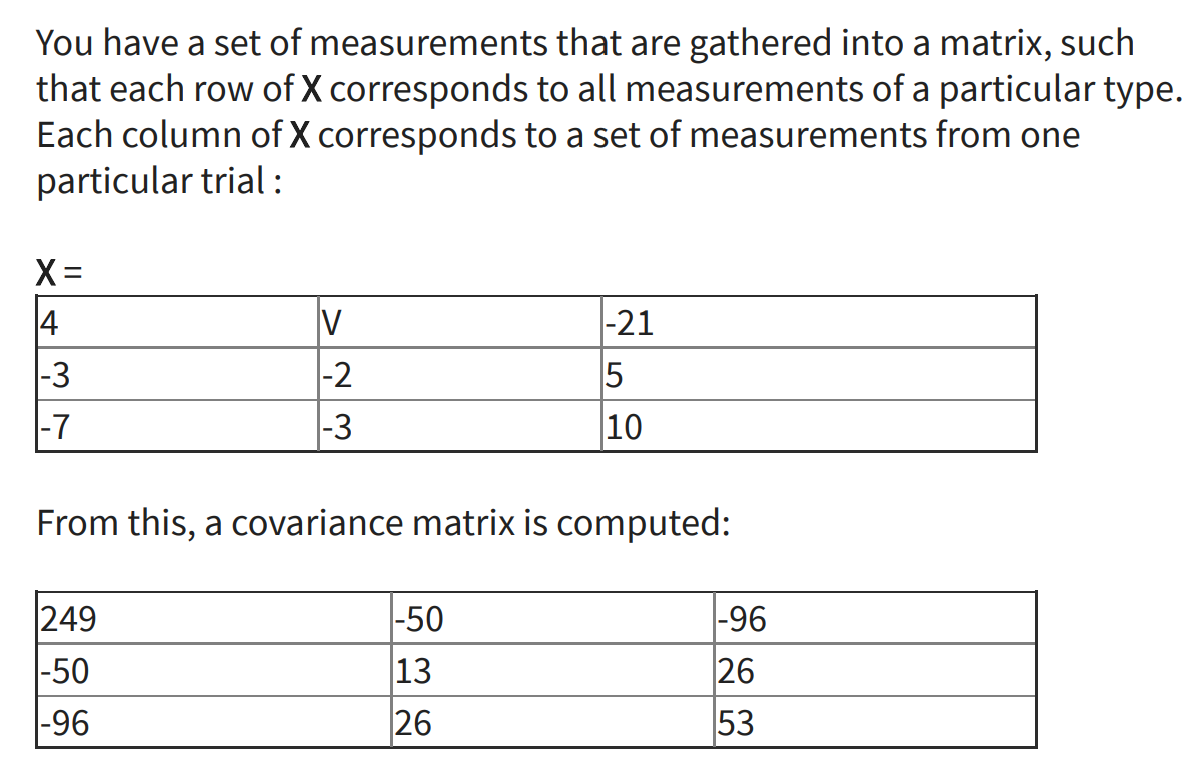

Wht is the missing value V?

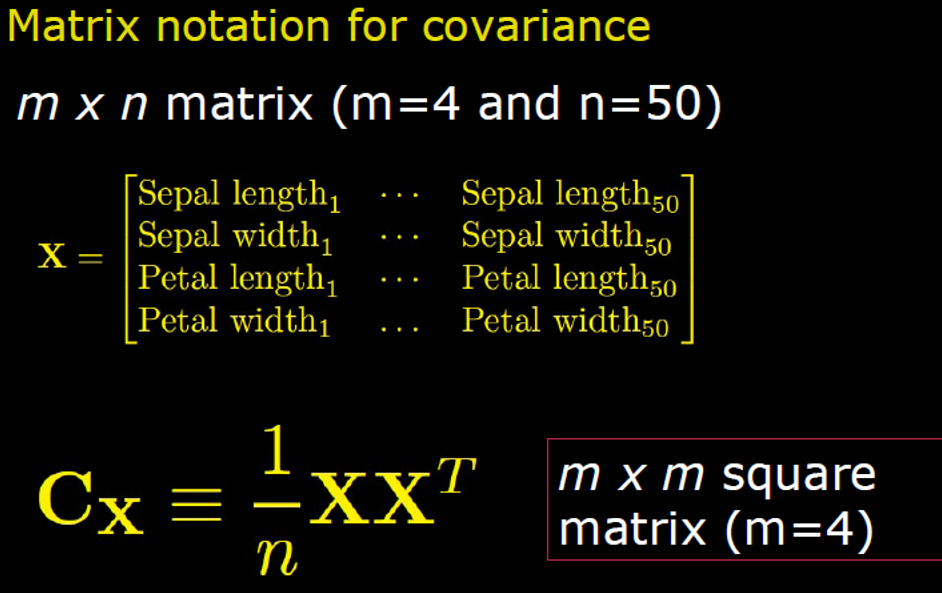

for V=[17,4,13,6,7] 
X = [4 V -21; -3 -2 5; -7 -3 10]
% K = cov(X)
%C = 1/3 *X *(X')
C = exam_funcs.covariance_matrix(X)
end

X =      4    17   -21
    -3    -2     5
    -7    -3    10


C =   248.6667  -50.3333  -96.3333
  -50.3333   12.6667   25.6667
  -96.3333   25.6667   52.6667


X =      4     4   -21
    -3    -2     5
    -7    -3    10


C =   157.6667  -41.6667  -83.3333
  -41.6667   12.6667   25.6667
  -83.3333   25.6667   52.6667


X =      4    13   -21
    -3    -2     5
    -7    -3    10


C =   208.6667  -47.6667  -92.3333
  -47.6667   12.6667   25.6667
  -92.3333   25.6667   52.6667


X =      4     6   -21
    -3    -2     5
    -7    -3    10


C =   164.3333  -43.0000  -85.3333
  -43.0000   12.6667   25.6667
  -85.3333   25.6667   52.6667


X =      4     7   -21
    -3    -2     5
    -7    -3    10


C =   168.6667  -43.6667  -86.3333
  -43.6667   12.6667   25.6667
  -86.3333   25.6667   52.6667


## Opg. 2 g afstanden ude i virkeligheden: 

Your camera has a CCD chip that measures 6.5 x 4.5 mm and an image taken with the camera has 7800 x 5400 pixels. It can be assumed that f=b=2.3 mm. The camera has been used to take an image of a 50 cm high reference object. On the image, the object is 400 pixels high. 

How far away from the camera is the reference object?

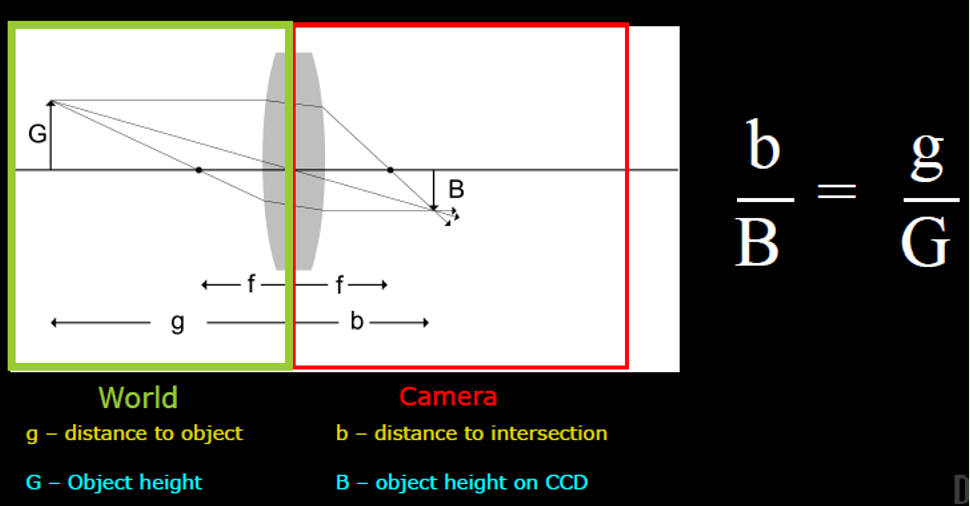

G = 500; %mm
b = 2.3;
B = 400; %pixels  % omregn pixels til mm 
B = B*4.5/5400;

g = (b*G)/B

g = 3450

%Derfor svar B 3.45 m

## Opg. 3 B størrelsen inde i kameraet: 

You have taken a photo of a DTU sign with a **width of 1.2 m from a distance of 7 m. **

The camera has a **CCD chip that measures (bredde)5.8 x (højde)4.2 mm and the image has 6960 x 5040 pixels**. It can be assumed that **f=b=1.5 mm. **

How many pixels wide will the sign be in the photo? 

clc; clear; close all; 
g = 7000; %7m i millimeter
G = 1200;
f = 1.5;
b= 1.5;



B = (b*G)/g

B = 0.2571

% omregn nu til pixels 
B = B*6960/5.8

B = 308.5714

%Derfor svar D 309



## Opg. 4: Field of view

You have taken a photo of building with a camera with a horizontal fieldof-view of 42 degrees. The building can just fit into the photo and the photo is taken from a distance of 7 m. 

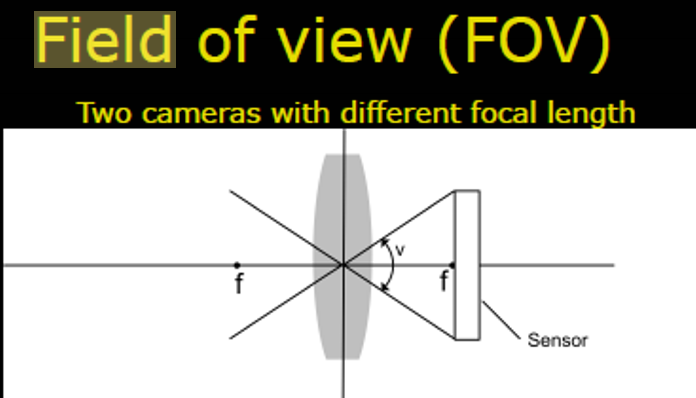

How wide is the building? 

Den_forste =tand(21)*7

Den_forste = 2.6870

Den_anden =tand(21)*7

Den_anden = 2.6870


Den_forste+Den_anden

ans = 5.3741

%Svar 5.4m A er det rigtige

## Opg. 5: Compactness and BLOB

A 5 x 5 image has been coded using a gray level run length code of : 3, 10, 3, 17, 1, 58, 1, 60, 4, 21, 3, 75, 2, 5, 6,8, 2, 2. This image is then thresholded with a threshold of 50 so pixels with values above are set to 1. Finally, a BLOB is found using 8-connectivity and the compactness of the BLOB is computed. The compactness is: 

clc; clear; close all; 

image = [10,10,10,17,17,17,58,60,21,21,21,21,75,75,75,5,5,8,8,8,8,8,8,2,2]

image =     10    10    10    17    17    17    58    60    21    21    21    21    75    75    75     5     5     8     8     8     8     8     8     2     2


image = reshape(image, 5, [])'

image =     10    10    10    17    17
    17    58    60    21    21
    21    21    75    75    75
     5     5     8     8     8
     8     8     8     2     2



% threshold
im_thres = imbinarize(image, 50)

im_thres = 5×5 logical array
   0   0   0   0   0
   0   1   1   0   0
   0   0   1   1   1
   0   0   0   0   0
   0   0   0   0   0



% now BLOB 
im_blob = bwconncomp(im_thres, 8)

im_blob = struct with fields:
    Connectivity: 8
       ImageSize: [5 5]
      NumObjects: 1
    PixelIdxList: {[5×1 double]}



compactness = regionprops(im_blob,"Extent")

compactness = struct with fields:
    Extent: 0.6250


% dette er altså 5 som er antal 1 taller, divideret med arealet 
% af den boks, der er rundt om dem. 


## Opg. 6: foreground pixels

A binary image using a 0-based (x, y) coordinate system has been coded using the binary run-length code: [2; (2, 3)], [3; (3, 4)], [3; (6, 6)], [4; (3,7)], [5; (4, 7)], [6; (5, 6)]. 

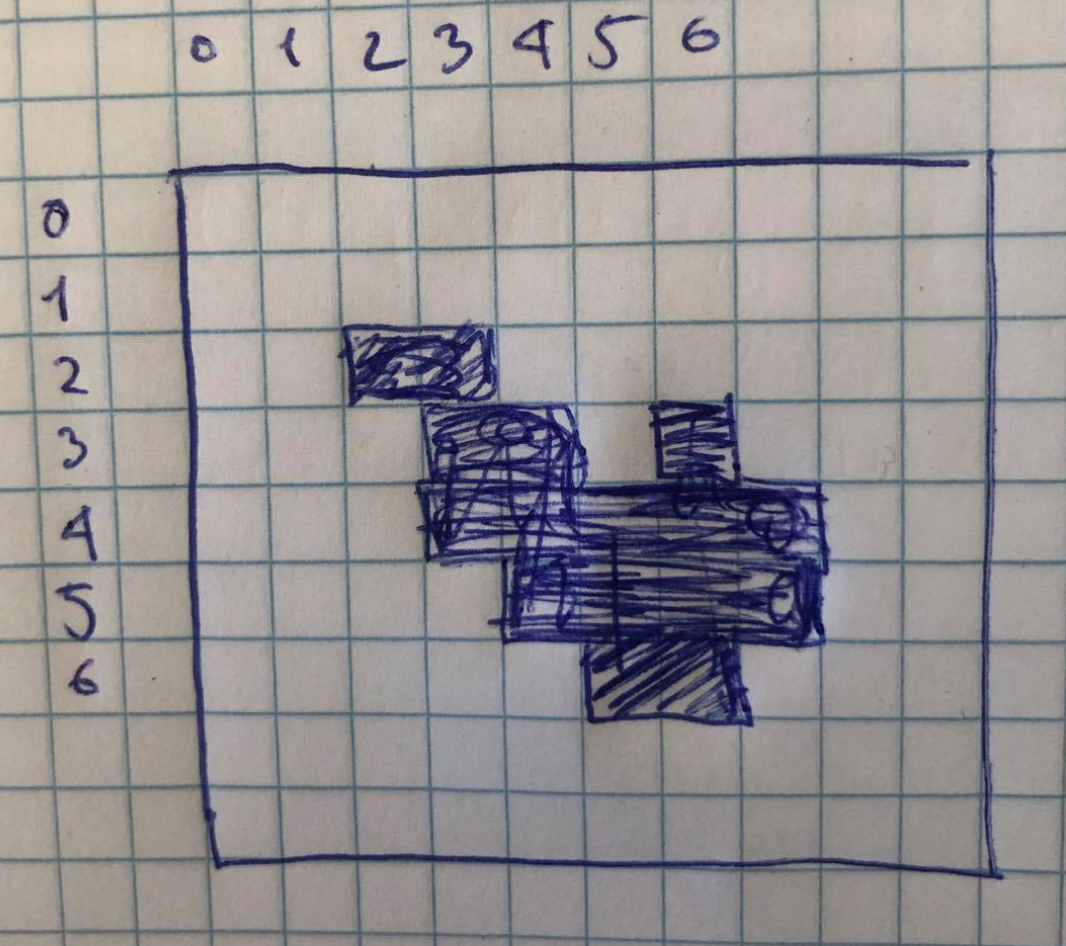

The decoded image (I) is processed with the morphological operation 

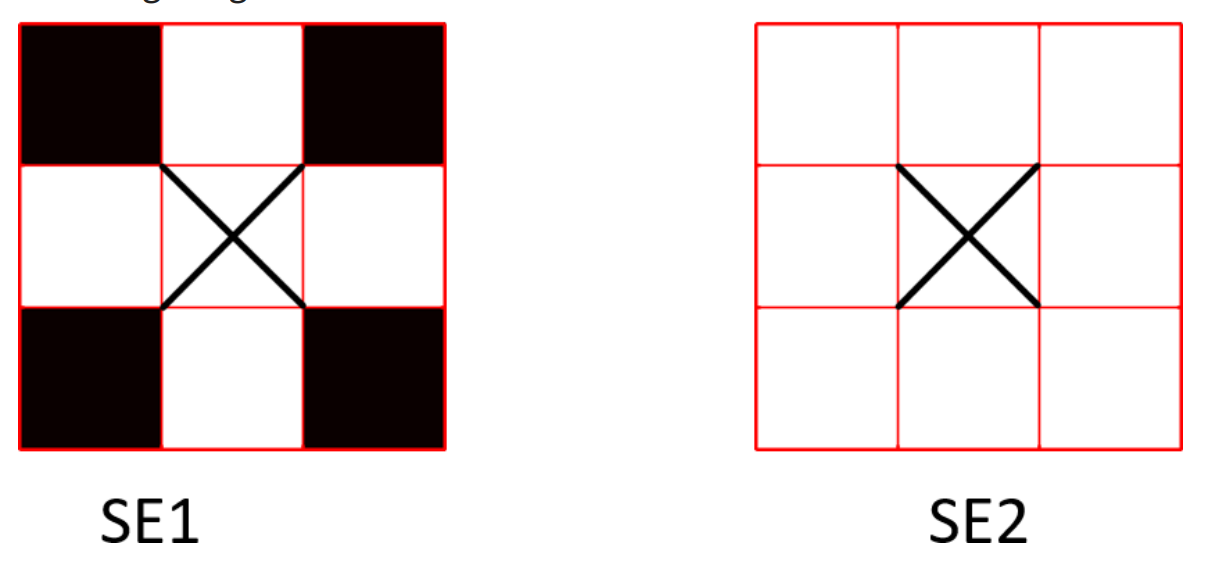

The cross in the structuring elements marks the center. How many foreground pixels are there in the resulting image? 

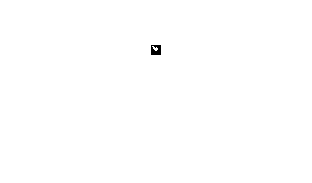

% Man kunne godt 1-indexere det, men det gør ikke noget i dette tilfælde,
% da vi bare skal have summen og der er bare 0'er udenom. Derfor har vi det
% bare som 0-indexeret som det er i opgavebeskrivelsen. 
im = zeros(10);
im(2, 2:3) = 1;
im(3, 3:4) = 1;
im(3, 6) = 1;
im(4, 3:7) = 1;
im(5, 4:7)=1;
im(6, 5:6)=1;

figure;
imshow(im)


SE1 = zeros(3);
SE1(2,1:3) = 1;
SE1(1:3,2) =1;
SE1

SE1 =      0     1     0
     1     1     1
     0     1     0



SE2 = ones(3);
SE2

SE2 =      1     1     1
     1     1     1
     1     1     1



% først erosion
im_eroded = imerode(im,SE1);

% Then closing
im_closed = imclose(im_eroded, SE2);

% sum af antal foreground pixels
sum(im_closed,"all")

ans = 5

## Opg. 7:RGB and HSI picture foreground pixels

The RGB image seen in the figure is converted to the HSI color space. The pixels are thresholded by a threshold of 0.8 on the S values, so pixels with values above are set to foreground. 

How many foreground pixels are there in the resulting image?

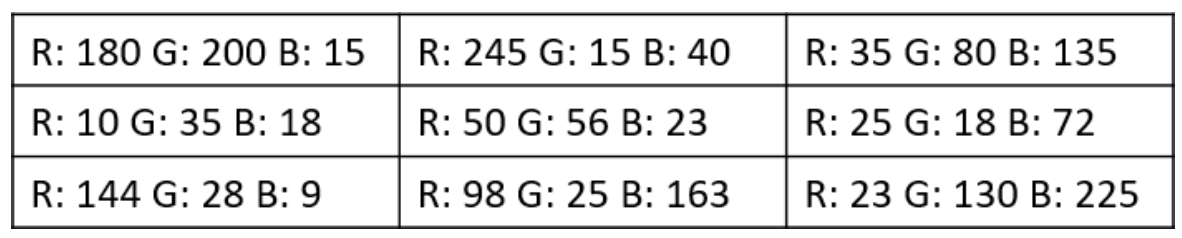

% først converter til HSI ved S formlen 

r = [180, 245, 35; 10, 50, 25; 144, 98, 23];
g = [200, 15, 80; 35, 56, 18; 28, 25, 130];
b = [15, 40, 135; 18, 23, 72; 9, 163, 225];

%exam_funcs.RGB_to_S(r,g,b)

im_rgb = cat(3, r,g,b)

im_rgb = im_rgb(:,:,1) =

   180   245    35
    10    50    25
   144    98    23


im_rgb(:,:,2) =

   200    15    80
    35    56    18
    28    25   130


im_rgb(:,:,3) =

    15    40   135
    18    23    72
     9   163   225



im_hsi = exam_funcs.RGB_to_HSI(im_rgb)

im_hsi = im_hsi(:,:,1) =

    0.1824    0.9842    0.5925
    0.3840    0.1940    0.6857
    0.0208    0.7553    0.5779


im_hsi(:,:,2) =

    0.8861    0.8500    0.5800
    0.5238    0.4651    0.5304
    0.8508    0.7378    0.8175


im_hsi(:,:,3) =

    0.5163    0.3922    0.3268
    0.0824    0.1686    0.1503
    0.2366    0.3739    0.4941


im_s = im_hsi(:,:,2)

im_s =     0.8861    0.8500    0.5800
    0.5238    0.4651    0.5304
    0.8508    0.7378    0.8175



im_thres_s = imbinarize(im_s, .8)

im_thres_s = 3×3 logical array
   1   1   0
   0   0   0
   1   0   1


sum(im_thres_s, "all")

ans = 4

## Opg. 8: normalized cross correlation

A linear gray level transformation is applied to the image seen to the left. The desired minimum pixel value is 12 and the desired maximum pixel value is 196. After the transformation, the pixel values are rounded to the nearest integer. 

A template match is applied to the resulting image, with the template seen to the right. 

What is the normalized cross correlation in the marked pixel? 

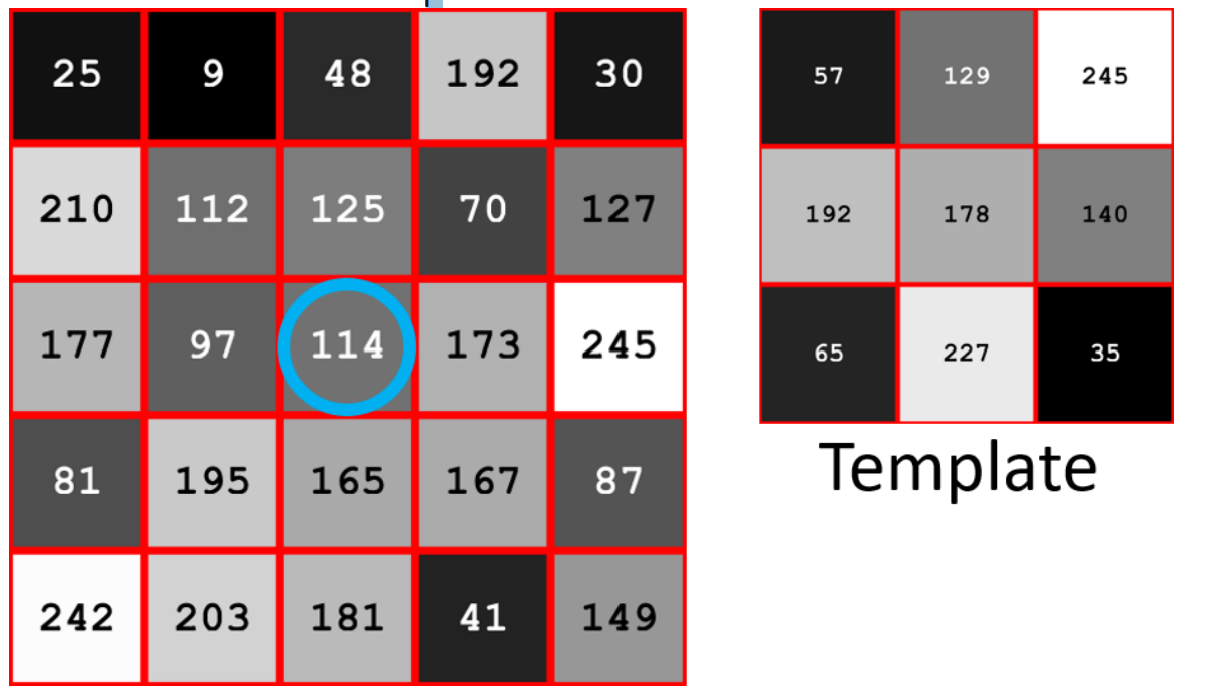

% Histogram stretching formula will be used. 

clc; clear; close all; 

image = [25,9,48,192,30;210,112,125,70,127;177,97,114,173,245;81,195,165,167,87;242,203,181,41,149]

image =     25     9    48   192    30
   210   112   125    70   127
   177    97   114   173   245
    81   195   165   167    87
   242   203   181    41   149


v_min_d = 12

v_min_d = 12

v_max_d = 196

v_max_d = 196

v_min = min(image, [], "all")

v_min = 9

v_max = max(image, [], "all")

v_max = 245

image = ((v_max_d - v_min_d)/(v_max - v_min))*(image - v_min) + v_min_d

image =    24.4746   12.0000   42.4068  154.6780   28.3729
  168.7119   92.3051  102.4407   59.5593  104.0000
  142.9831   80.6102   93.8644  139.8644  196.0000
   68.1356  157.0169  133.6271  135.1864   72.8136
  193.6610  163.2542  146.1017   36.9492  121.1525


image = round(image)

image =     24    12    42   155    28
   169    92   102    60   104
   143    81    94   140   196
    68   157   134   135    73
   194   163   146    37   121



template = [57,129,245;192,178,140;65,227,35]

template =     57   129   245
   192   178   140
    65   227    35


v_min_d_temp = 12

v_max_d_temp = 196

v_min_temp = 35

v_max_temp = 245


corr_2d = sum(image(2:4, 2:4).*template, "all") % indexeringerne er i forhold til at 

corr_2d = 130334

% vi skal have punktet 3,3 i midten af templaten, og vi skal udtage samme
% størrelse som vi har template. 
image_patch_len = sqrt(sum(image(2:4, 2:4).^2, "all"))

image_patch_len = 343.9404

template_patch_len = sqrt(sum(template.^2, "all"))

template_patch_len = 474.3859

NCC = corr_2d/(image_patch_len*template_patch_len)

NCC = 0.7988

## Opg. 9: gammamapping, gradient estimation with prewitt

A gamma mapping with gamme = 1.7 is applied to the image below and the resulting pixel values are rounded to integers. Secondly, the gradient in each pixel is approximated using the horizontal and vertical Prewitt filters. 

What is the magnitude of the gradient in the marked pixel? 

clc; clear; close all; 

image = [208,25,40,36,167;231,71,248,108,9;32,139,244,234,217;233,244,124,202,238;161,246,204,245,173]

image =    208    25    40    36   167
   231    71   248   108     9
    32   139   244   234   217
   233   244   124   202   238
   161   246   204   245   173


im_gamma_mapped = exam_funcs.GammaMap(image,1.7)

im_gamma_mapped =    180     5    11     9   124
   216    29   243    59     1
     7    91   237   220   194
   219   237    75   172   227
   117   240   174   238   132



prewitt_filter = [-1,0,1;-1,0,1;-1,0,1] % vertical

prewitt_filter =     -1     0     1
    -1     0     1
    -1     0     1



first = imfilter(im_gamma_mapped,prewitt_filter)

first =     34  -142    34  -129   -68
   125    88   163  -172  -288
   357   113    94  -133  -451
   568   143    62    67  -630
   477   -87   -67   110  -410


second = imfilter(im_gamma_mapped,prewitt_filter')

second =    245   488   331   303    60
   -87   139   523   507   281
   211    43   153   171   339
   259   196   104  -107   -44
  -456  -531  -484  -474  -399



%What is the magnitude of the gradient in the marked pixel
sqrt(first(3,2)^2 + second(3,2)^2)

ans = 120.9049

## Opg. 10: PCA 

A principal component analysis has been performed on a set of 3x3 images. The average image can be seen below and the 3 first Eigenvectors can be seen as columns in the matrix. A new image is synthesized by adding a linear combination of the 3 first Eigenvectors to the average image. The weights used are 

 what is the resulting pixel value in the upper left corner? 

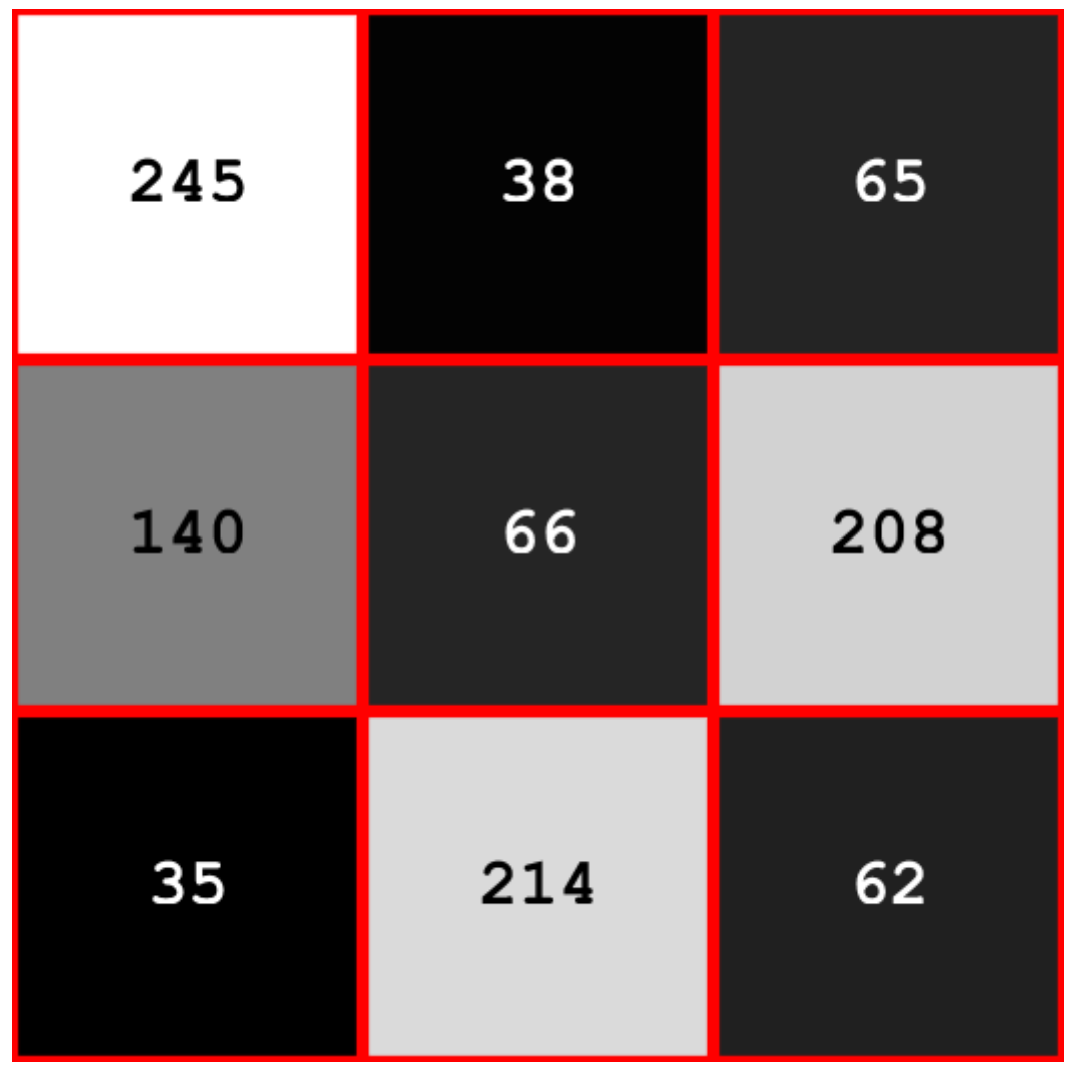

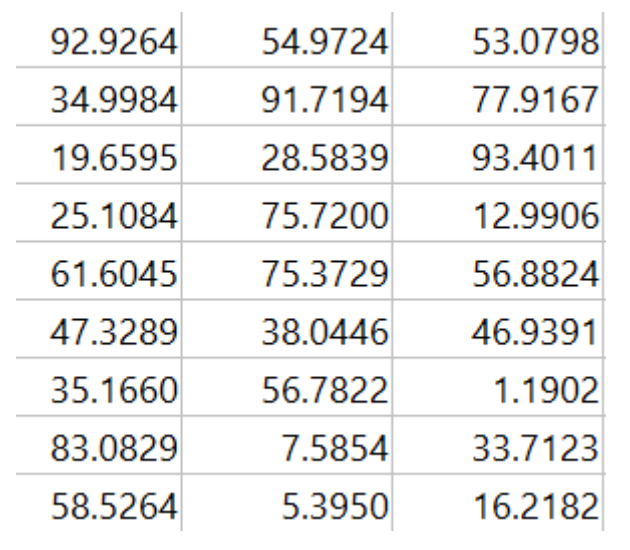

clc; clear; close all; 

image = [245,38,65,140,66,208,35,214,62]

image =    245    38    65   140    66   208    35   214    62


First_row_matrix = [92.9264*0.2,54.9724*-0.7,53.0798*0.5]

First_row_matrix =    18.5853  -38.4807   26.5399



Resulting_pixel_value_of_245 = sum(First_row_matrix)+245

Resulting_pixel_value_of_245 = 251.6445

## Opg. 11: Max-Rank filter - precision and thresholding 

A 3x3 max-rank filter is applied to the image below. 0-padding is used to handle the border problem. This is followed by a threshold of 250, where pixels with values above are set to foreground. The resulting image is considered as the result of a pixel classification, where a foreground pixel is considered positive and the rest negative. The ground truth image can be seen further below. 

What is the precision of the algorithm?

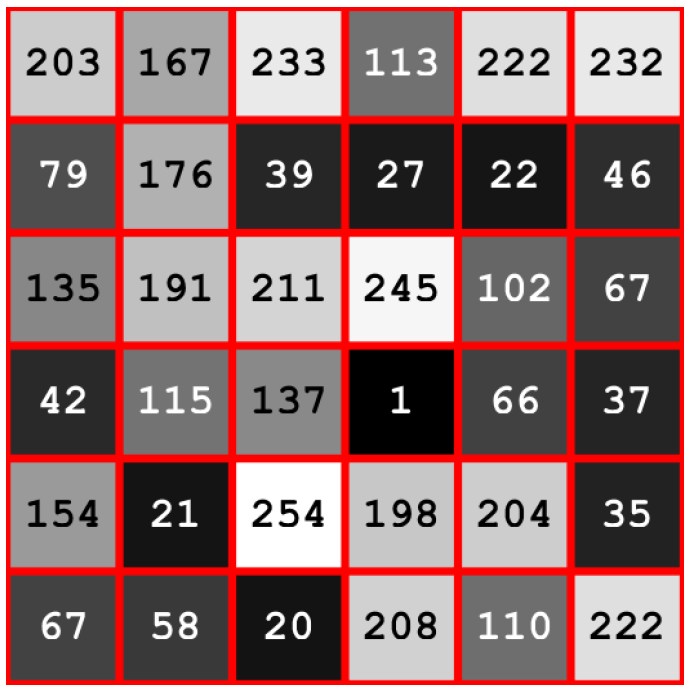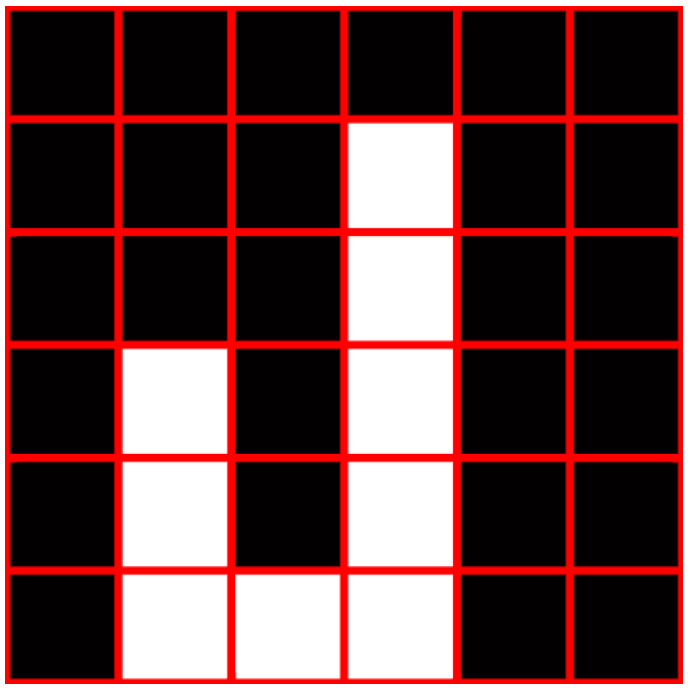

clc; clear; close all; 

img = [203 167 233 113 222 232; 79 176 39 27 22 46; 135 191 211 245 102 67; 
    42 115 137 1 66 37; 154 21 254 198 204 35; 67 58 20 208 110 222]

img =    203   167   233   113   222   232
    79   176    39    27    22    46
   135   191   211   245   102    67
    42   115   137     1    66    37
   154    21   254   198   204    35
    67    58    20   208   110   222



% apply a max rank filter
img_filtered = ordfilt2(img,9,ones(3,3))

img_filtered =    203   233   233   233   232   232
   203   233   245   245   245   232
   191   211   245   245   245   102
   191   254   254   254   245   204
   154   254   254   254   222   222
   154   254   254   254   222   222



% threshold image
img_thresh = img_filtered > 250

img_thresh = 6×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   1   1   1   0   0
   0   1   1   1   0   0
   0   1   1   1   0   0


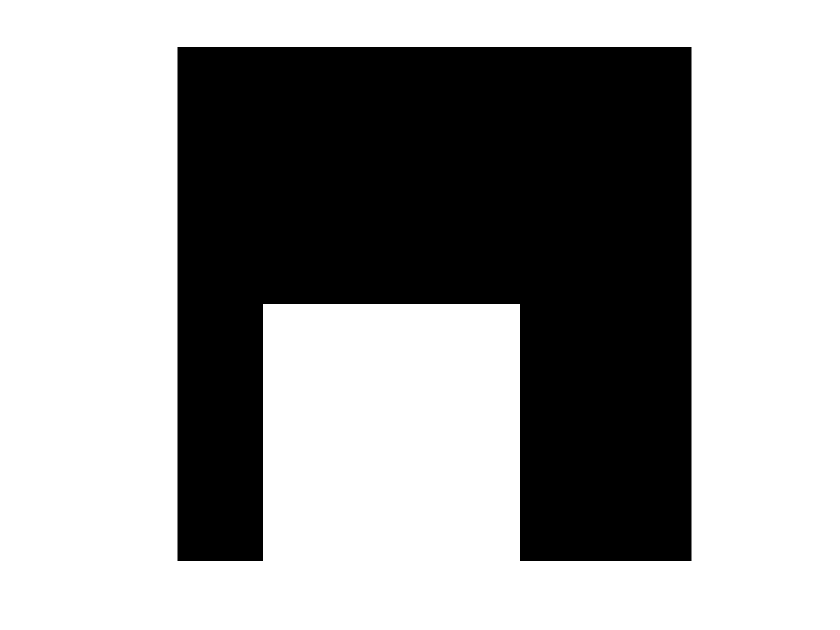

figure; imshow(img_thresh, 'InitialMagnification', 'fit')

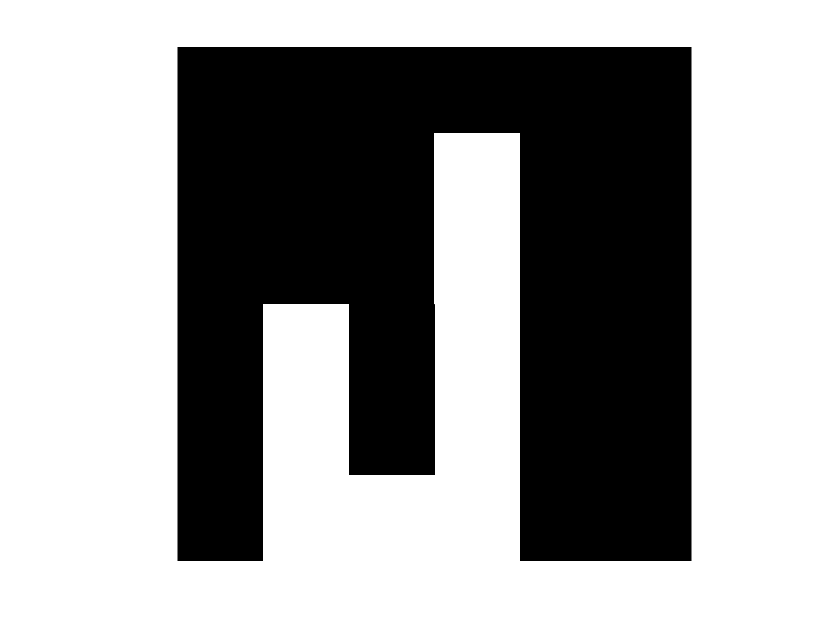


% get conf matrix values
img_true = zeros(6,6); 
img_true(4:6, 2) = 1;
img_true(6, 3) = 1;
img_true(2:6, 4) = 1;
figure; imshow(img_true, 'InitialMagnification', 'fit')


TP = sum(img_true == 1 & img_thresh == 1, "all")

TP = 7

FP = sum(img_true == 0 & img_thresh == 1, "all")

FP = 2


precision = TP/(TP+FP)

precision = 0.7778

## Opg 12: BLOB and feature space 

A BLOB analysis is performed on the image below using 4-connectivity. The following BLOB features are computed for the two found BLOBs: area, bounding box ratio, and compactness. What is the Euclidean distance between the two BLOBs in feature space?

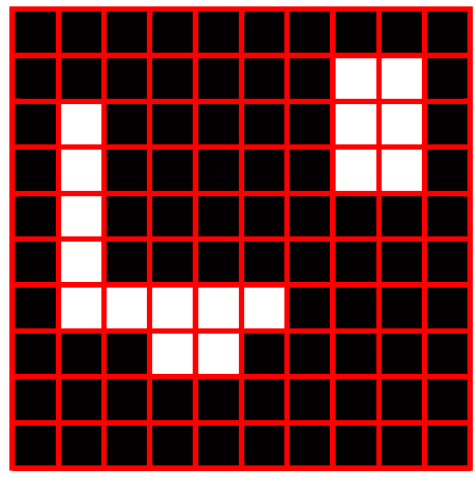

clc; clear; close all; 
img = zeros(10, 10);
img(3:7, 2) = 1;
img(7, 3:6) = 1;
img(8, 4:5) = 1;
img(2:4, 8:9) = 1;
img

img =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     1     0
     0     1     0     0     0     0     0     1     1     0
     0     1     0     0     0     0     0     1     1     0
     0     1     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


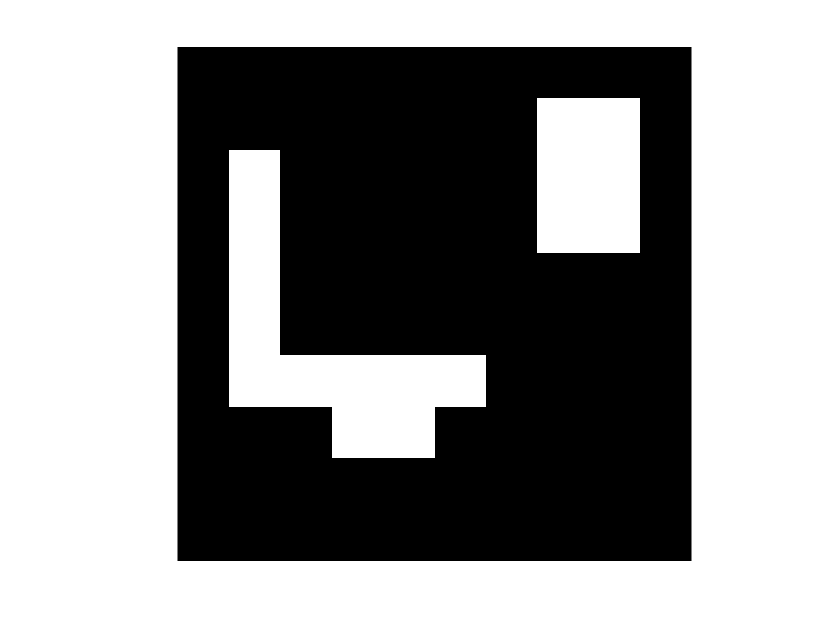

figure; imshow(img, 'InitialMagnification', 'fit')
exam_funcs.imagegrid(gca, size(img));

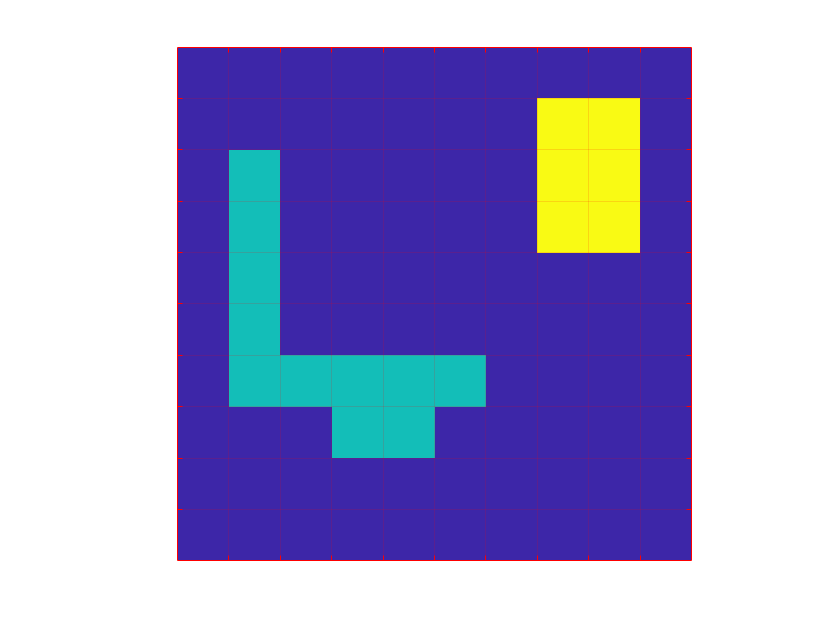


L4 = bwlabel(img, 4);
imagesc(L4);
exam_funcs.imagegrid(gca, size(L4));


% calculate features
stats4 = regionprops(L4, 'All');

% areas
A1 = stats4(1).Area;
A2 = stats4(2).Area;

% bounding box ratio
[H1, W1] = (size(stats4(1).FilledImage));
BBR1 = H1/W1

BBR1 = 1.2000

[H2, W2] = (size(stats4(2).FilledImage))

H2 = 3

W2 = 2

BBR2 = H2/W2

BBR2 = 1.5000


% bounding box area
BBA1 = prod(size(stats4(1).FilledImage));
BBA2 = prod(size(stats4(2).FilledImage));

% compactness
C1 = A1/BBA1;
C2 = A2/BBA2;

% euclidian distance
distance = sqrt((A1-A2)^2 + (BBR1-BBRs2)^2 + (C1-C2)^2)

distance = 5.0489

## Opg 13: Accuracy of BLOB classification

A BLOB analysis is performed on the image below using 4-connectivity, where all pixels that are not black are considered foreground. This is followed by a BLOB classification, where BLOBs with an area less than 5 are classified as positive and the rest as negative. The ground truth is marked so white BLOBs are negative and orange BLOBs are positive.

What is the accuracy of the classification algorithm?

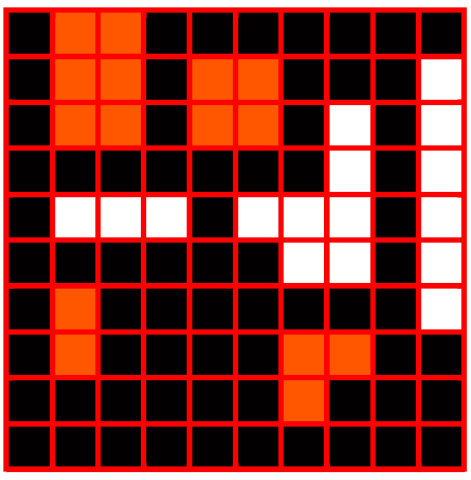


$$acc = \frac{TP+TN}{N}$$


clc; clear; close all; 
TP = 3;
FP = 1;
TN = 2;
FN = 1;
N = TP+FP+TN+FN;
acc = (TP+TN)/N

acc = 0.7143

## Opg 14: Some statements

Mark the incorrect statement below:

- When doing shape analysis, a shape represented by landmarks can be considered a point in a high-dimensional space

- Point correspondence means that a landmark on one shape is placed on the same location on a similar shape

- When doing principal component analysis on a set of shapes, The first Eigenvector describes the average shape -> FALSE (the first eigenvector describes the feature with the most variance)

- A statistical shape model can be used as a generative model for shapes

- An iterative optimizer solves an optimization problem by performing many small operations over and over

## Opg 15: Minimum distance classifier

We would like to make a system that can classify tables, chairs and floors in indoor photos. For that a minimum distance classifier is used. An expert has marked representative regions in the image below, where the table is marked with blue, the chair is marked with green and the floor is marked with yellow. What are the resulting class ranges?

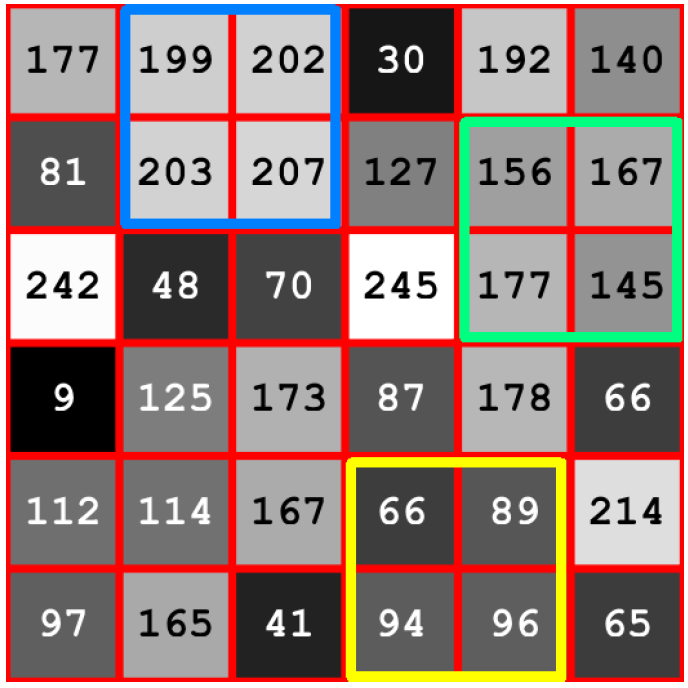

clc; clear; close all; 
table = [199, 202, 203, 207];
chair = [156, 167, 177, 145];
floor = [66, 89, 94, 96];

mu_table = mean(table)

mu_table = 202.7500

mu_chair = mean(chair)

mu_chair = 161.2500

mu_floor = mean(floor)

mu_floor = 86.2500


T1 = (mu_floor+mu_chair)/2

T1 = 123.7500

T2 = (mu_chair+mu_table)/2

T2 = 182

Svar: [0, 123], [124, 182], ]182, 255]

## Opg 16: Parametric classification - Gaussian Classifier

An underwater photo has been taken and the goal is to use a parametric classifier to label the pixels into the following classes: rock, fish, plant, coral, and sand. An expert has marked regions in the photo: rock (pink), fish (blue), plant (green), coral (white), and sand (yellow). A pixel with value 100 will be classified as:

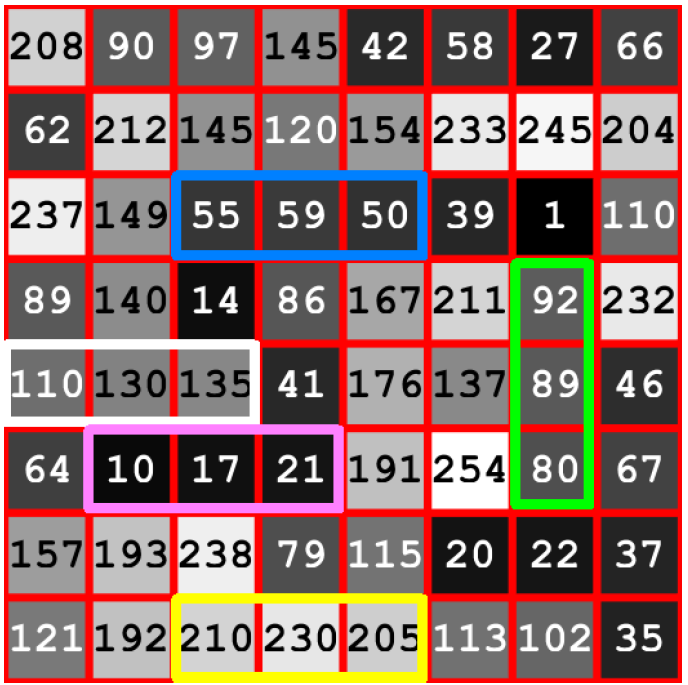

clc; clear; close all; 
x = 100;
rock = [10 17 21];
fish = [55 59 50];
plant = [92 89 80];
coral = [110 130 135];
sand = [210 230 205];

% lets look at some probabilities
p_rock = normpdf(x, mean(rock), std(rock))

p_rock = 2.6898e-51

p_fish = normpdf(x, mean(fish), std(fish))

p_fish = 9.9887e-24

p_plant = normpdf(x, mean(plant), std(plant))

p_plant = 0.0073

p_coral = normpdf(x, mean(coral), std(coral))

p_coral = 0.0051

p_sand = normpdf(x, mean(sand), std(sand))

p_sand = 1.1729e-18

Da plant har højst sandsynlighed, er dette den mest sandsynlige klasse

## Opg 17: bilinear interpolation - point on line profile

A line profile is sampled in an image with startpoint (x, y)=(15.3, 76.6) and endpoint (x, y)=(164.4, 13.3). The position in the middle of the profile is computed and the pixel value is sampled using bilinear interpolation.

The closest pixel values are:

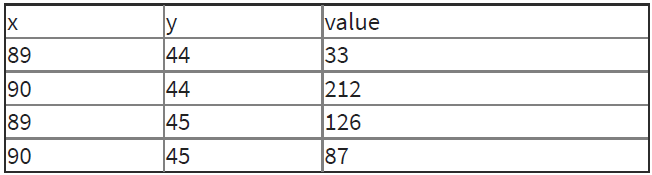

The found value is rounded to the nearest integer and the result is:

clc; clear; close all; 
X = [89 90 89 90];
Y = [44 44 45 45];
V = [33 212 126 87];
point = [(15.3+164.4)/2 (76.6+13.3)/2]';


ans = 97.4650

exam_funcs.BilinearInterpolation(point, X, Y, V)

## Opg 18: Some statements

Mark the incorrect statement below:

- When using a lossy image format when storing an image, you are not guarenteed that the pixel values are exactly the same as in the original image

- When fitting an active shape model to a new image, one approach is that each point of the shape model is moved to where there is a high gradient in the image.

- Having a strong prior in a statistical shape model can mean that an image that contains a sign of sickness can be fitted to look like a healthy person. 

- The first Eigenvector describes the major variation seen in a data set

- Automatic thresholding is based on morphological opening -> FALSE (No, it is based on pixel variance within the two classes foreground and background)

## Opg 19: Parametric classification - find optimal threshold

Big-data analysis of traffic camera images in New York has shown that photos of traffic signs and traffic lights both can be described by normal distributions of intensity values. You are asked to use parametric image classification to find the optimal threshold between the two classes. The two distributions are:

- Traffic signs: $\mathcal{N}(7, 2^2)$

- Traffic lights: $\mathcal{N}(15,5^2)$

What is the threshold?

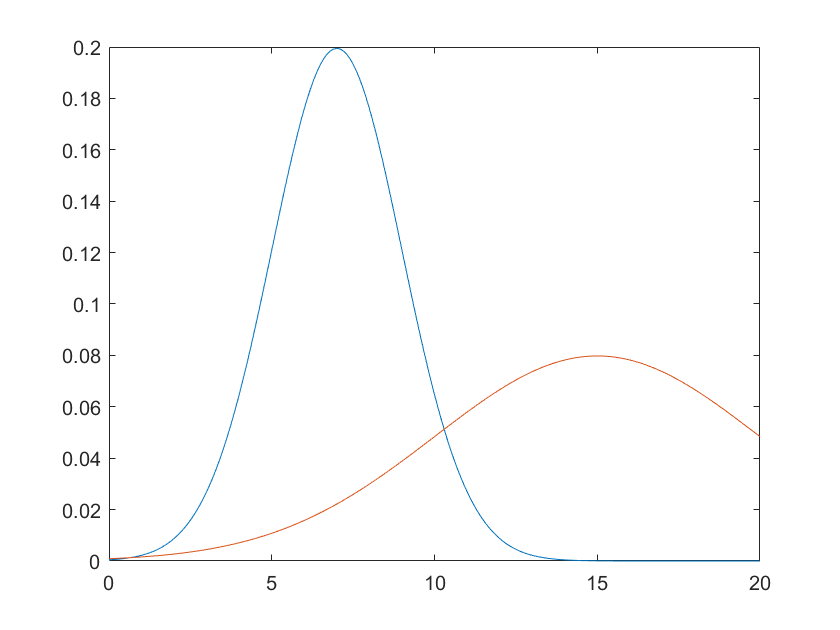

clc; clear; close all; 
xrange=0:0.1:20;
signs = normpdf(xrange, 7, 2);
lights = normpdf(xrange, 15, 5);

figure;
plot(xrange, signs); hold on
plot(xrange, lights)

Open image in new tab and click on intersection

## Opg 20: Squared distance objective function

To be able to do a landmark-based image registration between a reference image and a template image, two sets of corresponding landmarks have been placed in the two images. The landmarks can be seen in the table:

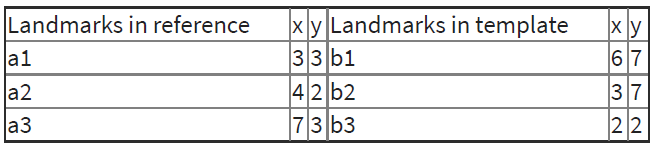

Before the registration, the first point in the reference image is rotated with $11^{o}$ using a rotation matrix (rotating counter-clockwise). What is the squared distance objective function F between the two point-sets?

clc; clear; close all; 
a1 = [3; 3];
a2 = [4; 2];
a3 = [7; 3];
b1 = [6; 7];
b2 = [3; 7];
b3 = [2; 2];

a1_rot = exam_funcs.rotate2d(a1, 11);
a2_rot = exam_funcs.rotate2d(a2, 11);
a3_rot = exam_funcs.rotate2d(a3, 11);

diff1 = (a1_rot(1)-b1(1))^2 + (a1_rot(2)-b2(2))^2;
diff2 = (a2(1)-b2(1))^2 + (a2(2)-b2(2))^2;
diff3 = (a3(1)-b3(1))^2 + (a3(2)-b3(2))^2;

F = diff1 + diff2 + diff3

F = 77.2882

## Opg 21:

To be able to do a landmark-based image registration between a reference image and a template image, two sets of corresponding landmarks have been placed in the two images. The landmarks can be seen in the table:

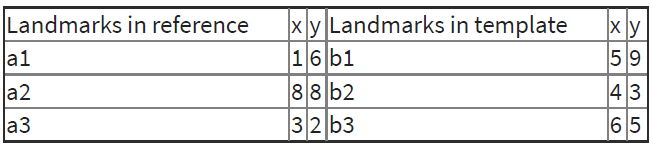

The points in the reference image are translated using a translation vector of t=(-2, 5). What is the change in the squared distance objective function F between the two point-sets?

clc; clear; close all; 
a1 = [1; 6];
a2 = [8; 8];
a3 = [3; 2];
b1 = [5; 9];
b2 = [4; 3];
b3 = [6; 5];

t = [-2; 5];

a1_trans = a1+t;
a2_trans = a2+t;
a3_trans = a3+t;

diff1_trans = (a1_trans(1)-b1(1))^2 + (a1_trans(2)-b1(2))^2;
diff2_trans = (a2_trans(1)-b2(1))^2 + (a2_trans(2)-b2(2))^2;
diff3_trans = (a3_trans(1)-b3(1))^2 + (a3_trans(2)-b3(2))^2;

diff1 = (a1(1)-b1(1))^2 + (a1(2)-b2(2))^2;
diff2 = (a2(1)-b2(1))^2 + (a2(2)-b2(2))^2;
diff3 = (a3(1)-b3(1))^2 + (a3(2)-b3(2))^2;

F_trans = diff1_trans + diff2_trans + diff3_trans;
F = diff1 + diff2 + diff3;

F_diff = F_trans-F

F_diff = 89



diff1 = (a1(1)-a1_trans(1))^2 + (a1(2)-a1_trans(2))^2;
diff2 = (a2(1)-a2_trans(1))^2 + (a2(2)-a2_trans(2))^2;
diff3 = (a3(1)-a3_trans(1))^2 + (a3(2)-a3_trans(2))^2;

F = diff1 + diff2 + diff3

F = 87

## Opg 22: Accumulator image

An optimal path from the top to the bottom of the image seen below is found using dynamic programming. What is the value of the accumulator image at the marked pixel position?

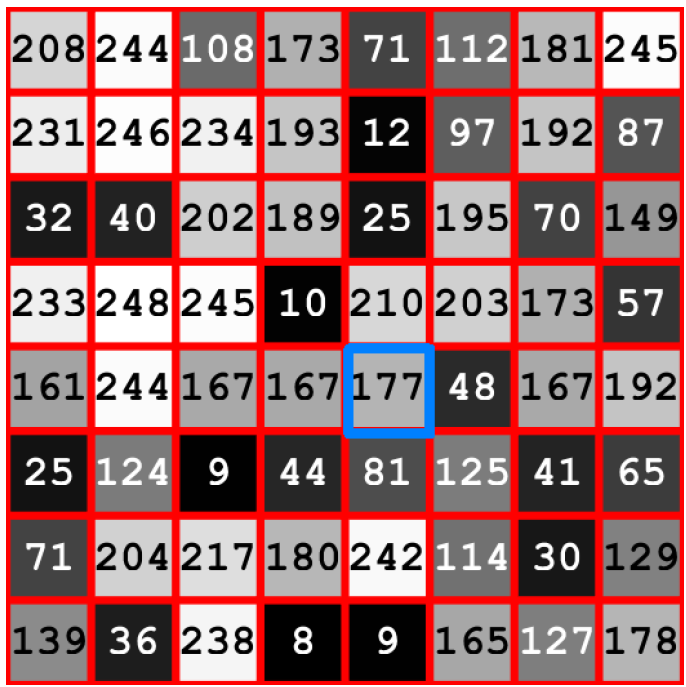

clc; clear; close all; 
177+10+25+12+71

ans = 295

## OPg 23: Pipeline for plant identification

A company producing farming machines wants you to develop an automated system for plant identification. The specific plant typically has red leaves and is o􀁸en found on brown farmland surrounded by green crops. What could be the pipeline that you would use to solve the task?

- Image acquisition, HSI color thresholding, morphological operations, BLOB analysis, feature classification -> This one

- Image acquisition, landmark registration, chain coding

- Binary run-length coding, PCA analysis, histogram stretching, morphological closing

- Hough transformation, parametric classification, confusion matrix, grey-level run length coding

- Gaussian filtering, active shape model, binary chain coding, automatic thresholding

These things does not make sense for an RGB image

- landmark registration

- binary run length encoding

- grey level run length encoding

- gaussian filtering (more blurry)

## Opg 24: Decision boundary

To make an image-based classification system for two di􀁷erent objects, a set of training images has been acquired and two features have been computed for all the objects in the images. In the image below, the two classes (the two types of objects) are plotted in feature space, where class one is blue and class two is orange. A linear discriminant analysis (LDA) has been performed and a decision boundary has been computed.

It can be described by which equation?

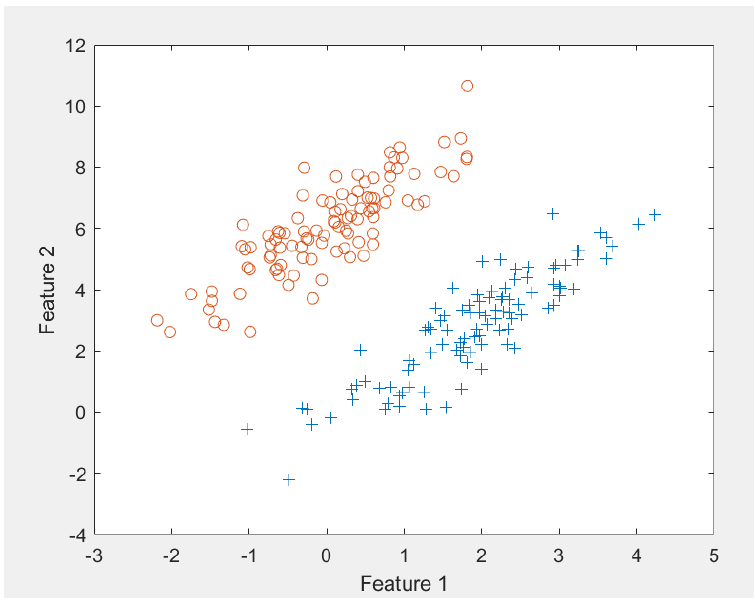

Positiv hældning og skæring med y-aksen et sted mellem 0 og 3

## Opg 25: Mean 

Two images have been registered using a state-of-the-art software package for image based registration. The registered images can be seen below. The mean squared difference (MSD) similarity metric was used for registration. What is the MSD for the two images?

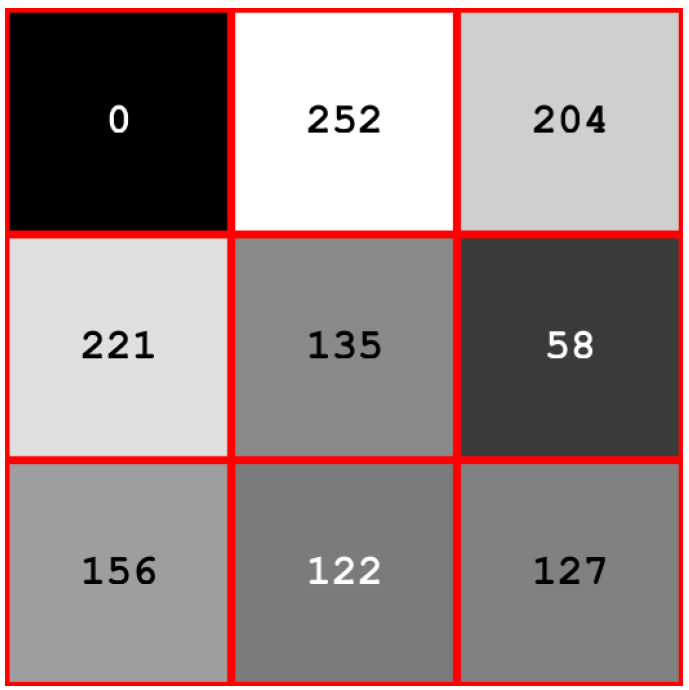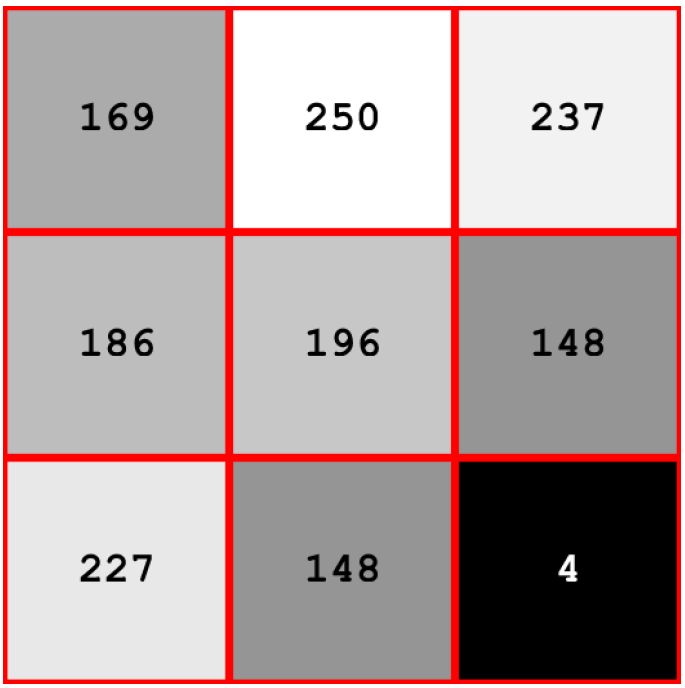

clc; clear; close all; 
I1 = [0 252 204; 221 135 58; 156 122 127];
I2 = [169 250 237; 186 196 148; 227 148 4];
format shortG
mean((I2-I1).^2, "all")

ans =        7060.7


# Test exam 2021

## Opg 1: Confusion Matrix - True Positive Rate

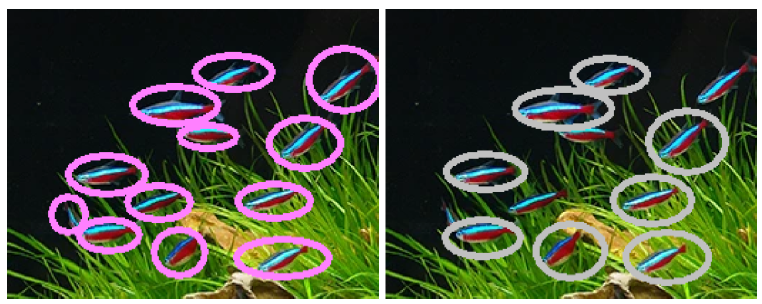

You have made an algorithm that can locate neon fish in an aquarium.

An expert has marked all neon fish in an image as seen in the image to the left. The result of your algorithm is seen in the figure to the right.

What is the true positive rate of your algorithm?

P_expert = 12;
P_algo = 8;
TP = P_algo;
FN = P_expert - P_algo;
TPR = TP/(TP+FN)

TPR = 0.6667

## Opg 2: Filtering/Morphology  - Foreground Pixels After Operations

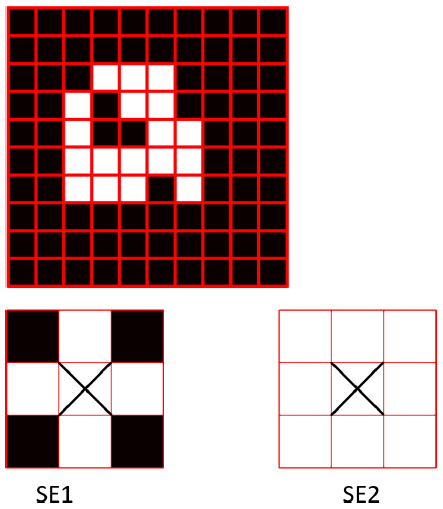

On the image (I) seen in the figure, the operation ($I\cdot SE2)\oplus SE1-1$ is performed. SE1 and SE2 are seen above. White pixels are foreground and black pixels are background. How many foreground pixels are there in the resulting image?

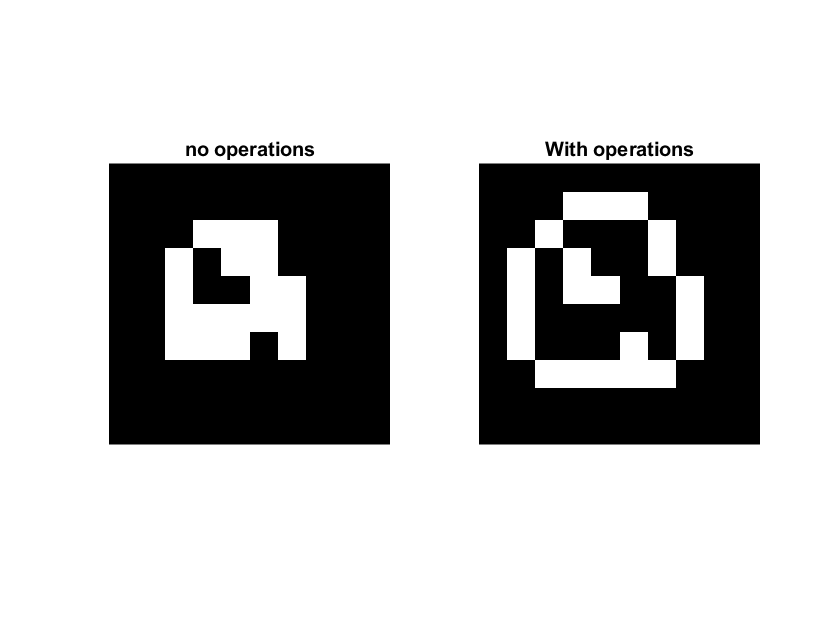

clc; close, clear all;
% define stuff
img = zeros(10,10);
img(3, 4:6) = 1;
img(4, [3, 5:6]) = 1;
img(5,[3, 6:7]) = 1;
img(6, 3:7) = 1;
img(7, [3:5, 7]) = 1;
figure;
subplot(1,2,1)
imshow(img, 'InitialMagnification','fit')
title("no operations")
SE1 = strel("disk", 1);
SE2 = strel("square", 3);

% perform operations
img_operation = imclose(img, SE2);
img_operation = imdilate(img_operation, SE1);
img_operation = img_operation-img;

subplot(1,2,2)
imshow(img_operation, 'InitialMagnification', 'fit');
title("With operations")


foreground_pixels = sum(img_operation, "all")

foreground_pixels = 22

## Opg 3

The point (x, y) = (10, 30) is transformed using a homography with the parameter vector $\vec{d}=[3, 1, 4, 2, 7, 6, 2, 1]^T$. What is the resulting

point (x', y')?

% not part of curriculum

## Opg 4

The point (x, y) = (33, 97) is rotated using a rotation matrix (rotating counter clockwise) with $\theta=8^{o}$. The closest four pixels to the transformed point and their pixel values are:

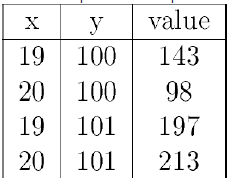

What is the interpolated value using bilinear interpolation (rounded to an integer) in the point?

close; clear all; clc;
Roteret_punkt = exam_funcs.rotate2d([33,97]',8);


X = [19 20 19 20];
Y = [100 100 101 101];
V = [143 98 197 213];

BilinearInterpo = exam_funcs.BilinearInterpolation(Roteret_punkt,X,Y,V);
BilinearInterpo

BilinearInterpo = 177.0586

## Opg 5

A camera without lens distortions has been used to take a movie of a flying bird. The bird is moving with a constant speed. The bird's path is parallel to the camera's horizontal axis and orthogonal to the optical axis of the camera. The movie has been taken with a distance of 20 meters from the optical center to the path of the bird. The field-of-view of the camera is $28^{o}$. The time from the bird is appearing in the left side of the image to it touches the right side of the image is 2 seconds. 

How fast is the bird flying?

% Husk at tage halvdelen af den opgivede vinkel

Den_forste =tand(28/2)*20

Den_forste = 4.9866

Den_anden =tand(28/2)*20

Den_anden = 4.9866


result = Den_forste+Den_anden

result = 9.9731


Fart = result/2

Fart = 4.9866

## opg 6

The photo called legocar.png is filtered using an average filter with a filter size of 10. The resulting image is thresholded, so pixels with a value larger than 200 is set to foreground and the rest is set to background. Finally, the BLOBS in the image is found. 

How many BLOBs are there?

## opg 7

Two sets of corresponding landmarks have been annotated on two photos of hands. The first set is called movingPoints.mat and the second fixedPoints.mat. 

The moving points are aligned to the fixed points using a similarity transform (rotation, scaling and translation). 

Finally, the found transform is applied to the first point of the moving points. 

What are the coordinates of the transformed point?

- Answer = 628.8854  303.0213

- see the forward variable from exercise 15 of exercise 7